Part 6.1

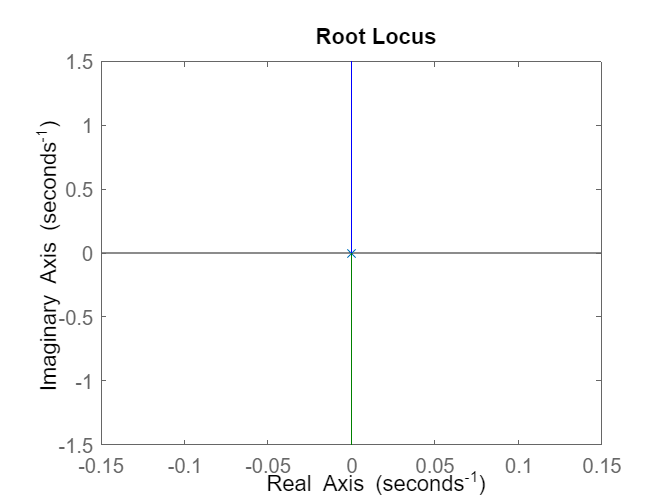

% Define system parameters
m = 2.5e-3;  % mass of the ball in kg
R = 20e-3;    % radius of the ball in meters
d = 40e-3;    % lever arm offset in meters
L = 0.25;    % length of the beam in meters
J = 5.735e-6; % moment of inertia of the ball in kg-m^2
g = 9.81;     % acceleration due to gravity in m/s^2

% Define open-loop transfer function
s = tf('s');
G = (m*g*d)/(s^2*L*(R^2/J + m));

% Plot root locus
rlocus(G);

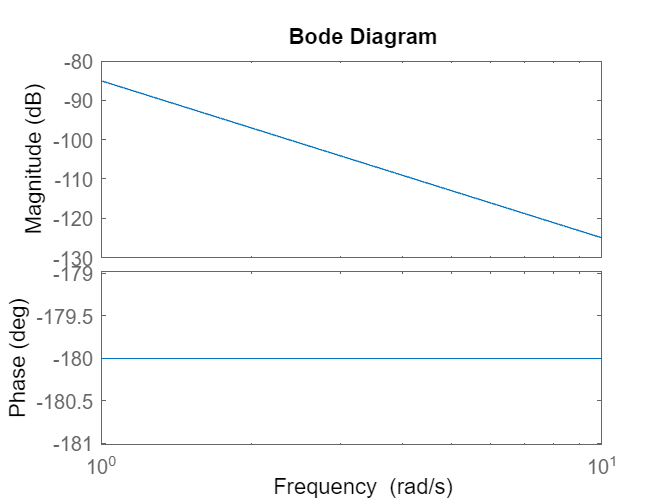


% Plot Bode plot
bode(G);


% Calculate phase margin and gain margin
[mag,phase,w] = bode(G);
[gm,pm,wcp,wcg] = margin(G);

fprintf('Phase Margin: %.2f deg\n', pm);

Phase Margin: 0.00 deg


fprintf('Gain Margin: %.2f dB\n', gm);

Gain Margin: 1.00 dB


Part 6.2

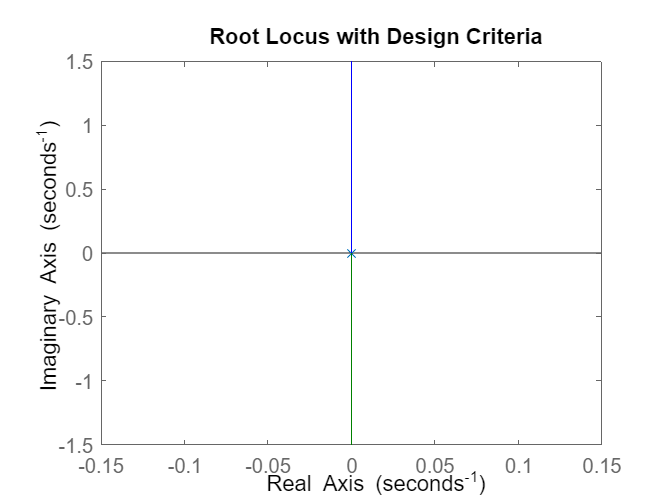

% Define design criteria
overshoot = 5;  % percent
settling_time = 3;  % seconds

% Define system parameters
m = 2.5e-3;  % mass of the ball in kg
R = 20e-3;    % radius of the ball in meters
d = 40e-3;    % lever arm offset in meters
L = 28e-2;    % length of the beam in meters
J = 5.735e-6; % moment of inertia of the ball in kg-m^2
g = 9.81;     % acceleration due to gravity in m/s^2

% Define open-loop transfer function
s = tf('s');
G = (m*g*d)/(s^2*L*(R^2/J + m));

% Plot root locus with design criteria
figure;
rlocus(G);
sgrid(overshoot, settling_time);
title('Root Locus with Design Criteria');

fprintf('Root locus is plotted with design criteria of %d%% overshoot and %d seconds settling time.\n', overshoot, settling_time);

Root locus is plotted with design criteria of 5% overshoot and 3 seconds settling time.


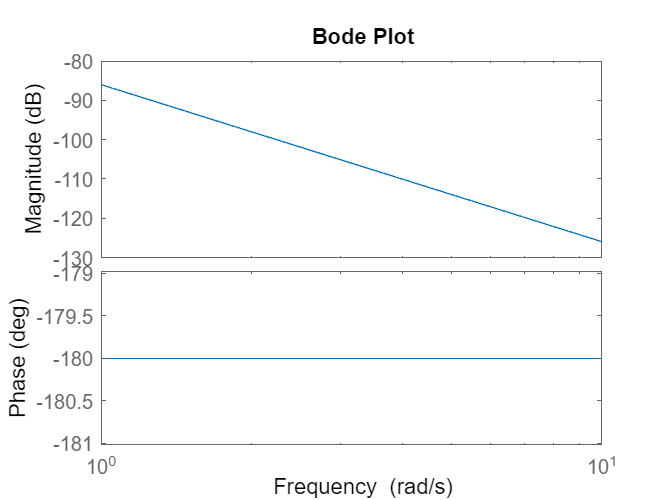


% Plot Bode plot
figure;
bode(G);
title('Bode Plot');

fprintf('Bode plot is plotted to analyze system frequency response.\n');

Bode plot is plotted to analyze system frequency response.


Comparision

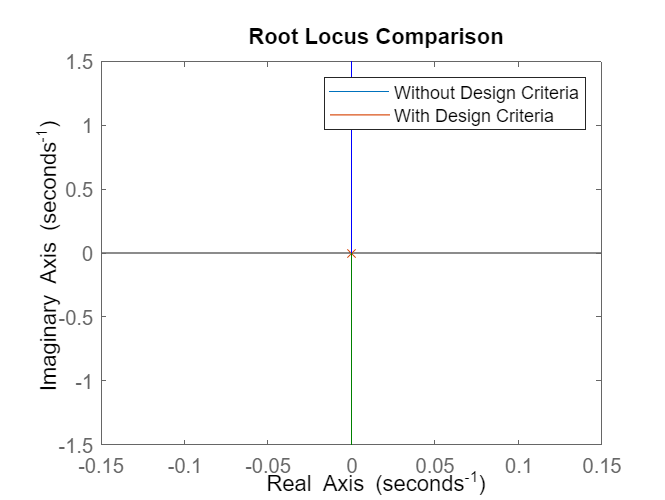

% Define system parameters
m = 2.5e-3;  % mass of the ball in kg
R = 20e-3;    % radius of the ball in meters
d = 40e-3;    % lever arm offset in meters
L = 0.25;    % length of the beam in meters
J = 5.735e-6; % moment of inertia of the ball in kg-m^2
g = 9.81;     % acceleration due to gravity in m/s^2

% Define open-loop transfer function
s = tf('s');
G = (m*g*d)/(s^2*L*(R^2/J + m));

% Define design criteria
overshoot = 5;  % percent
settling_time = 3;  % seconds

% Plot root locus with and without design criteria
figure;
rlocus(G);
hold on;
rlocus(G);  % plot without design criteria
sgrid(overshoot, settling_time);  % plot with design criteria
legend('Without Design Criteria', 'With Design Criteria');
title('Root Locus Comparison');

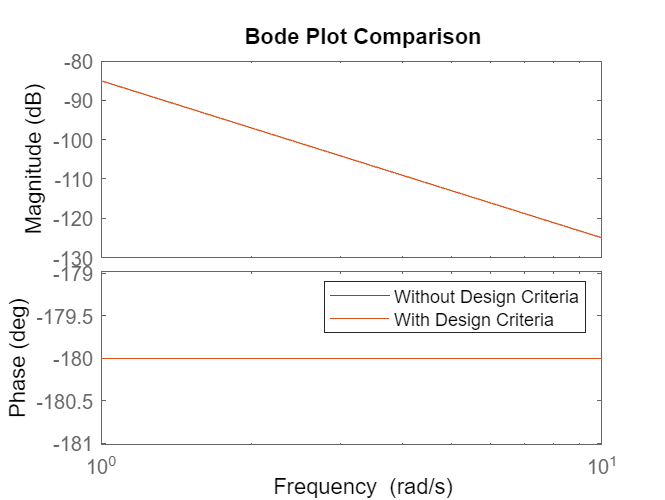


% Plot Bode plot with and without design criteria
figure;
bode(G);
hold on;
bode(G);  % plot without design criteria
legend('Without Design Criteria', 'With Design Criteria');
title('Bode Plot Comparison');


fprintf('Root locus and Bode plots are plotted for both design and no design criteria on the same graph.\n');

Root locus and Bode plots are plotted for both design and no design criteria on the same graph.


fprintf('Compare the plots to see the effect of design criteria on system performance.\n');

Compare the plots to see the effect of design criteria on system performance.
